mystartdefaults
step_size = 0.5;
x_min = -20;
x_max = 100;
x1_min = 0;
x1_max = 80;
n = (x_max - x_min)/step_size;
n1 = (x1_max - x1_min)/step_size;
tau = 1e-9;
gamma = (hbar * 2 * pi/tau)/qel;
recipunit=1.0E+10;
ekinscale=(hbar * recipunit)^2/(2 * elm)/qel;

U_total = zeros(1,n); % Potential barriers
x = zeros(1,n);
for i = 1:n
    x(i) = x_min + step_size/2 + (i - 1) * step_size;
    if x(i) >= 0 && x(i) <= 15
        U_total(i) = 0.2;
    elseif x(i) >= 65 && x(i) <= 80
        U_total(i) = 0.2;
    else
        U_total(i) = 0;
    end
end
U = zeros(1,n1); % Potential barrier
x1 = zeros(1,n1);
for i = 1:n1
    x1(i) = x1_min + step_size/2 + (i - 1) * step_size;
    if x1(i) <= 15
        U(i) = 0.2;
    elseif x1(i) >= 65 && x1(i) <= 80
        U(i) = 0.2;
    else
        U(i) = 0;
    end
end

E_resonance=[0.01075,0.04325,0.09525,0.16325,0.1312];
[~,n]=size(E_resonance);
W = zeros(length(U),length(U));

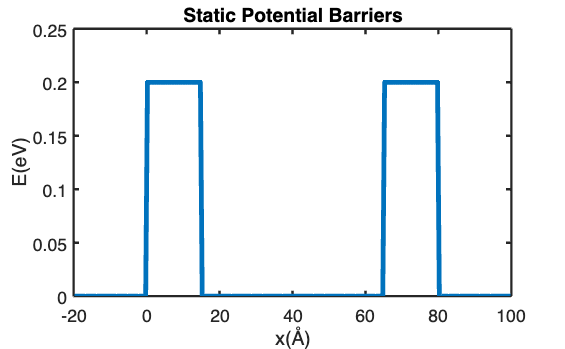

wave_func = zeros(n-1, length(U_total));
for i = 1:n
    k1 = sqrt((E_resonance(i) + 1i * gamma)/ekinscale);
    for j = 1:length(U)
        phi0k(j) = exp(1i * k1 * x1(j));
        W(j,j) = step_size * U(j)/ekinscale;
        for k = 1:length(U)
            G0(j,k) = Greenf(0,x1(j),x1(k),E_resonance(i),gamma,ekinscale);
        end
    end
    T = eye(length(U)) - G0 * W;
    phisol = T\(phi0k.');
    for j = 1:(length(U_total))
        if i < n
            wave_func(i,j) = exp(x(j) * 1i * k1) + outside_sol(x(j), x1, U, step_size, phisol, 0, E_resonance(i), gamma, ekinscale);
        else
            non_resonance_phi(j) = exp(x(j) * 1i * k1) + outside_sol(x(j),x1,U,step_size,phisol,0,E_resonance(i),gamma,ekinscale);
        end
    end
end
resonance_prob = abs(wave_func).^2;
non_resonance_prob = abs(non_resonance_phi).^2;
for i=1:length(U_total)    
  resonance_prob(1,i) = 0.0059 * resonance_prob(1,i) + E_resonance(1);
  resonance_prob(2,i) = 0.0019 * resonance_prob(2,i) + E_resonance(2);
  resonance_prob(3,i) = 0.0005 * resonance_prob(3,i) + E_resonance(3);
  resonance_prob(4,i) = 0.0030 * resonance_prob(4,i) + E_resonance(4); 
  non_resonance_prob(i) = 0.012 * non_resonance_prob(i) + E_resonance(n);
end
plot(x,U_total,'LineWidth',3);
title('Static Potential Barriers', 'FontSize',20);
ylim([0, 0.25]);
xlabel('x(Å)');
ylabel('E(eV)');
saveas(gcf, 'Static_Potential_Barriers.png');

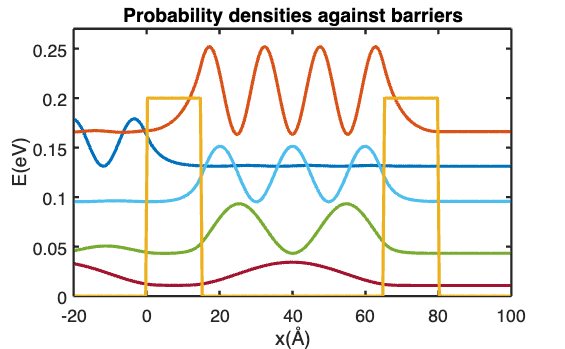

plot(x, non_resonance_prob, x,resonance_prob, x, U_total, 'LineWidth',2);
title('Probability densities against barriers','FontSize',20);
ylim([0, 0.27]);
xlabel('x(Å)');
ylabel('E(eV)'); 
saveas(gcf, 'prob_density.png')

function [Gf]= Greenf(step,x,xp,E,gamma,ekinscale) 
    ko=sqrt((E+1i*gamma)/ekinscale);
    k1=sqrt((E+1i*gamma-step)/ekinscale);
    if(x>=0 && xp>=0)
        Gf=exp(1i*k1*abs(x-xp))/(2i*k1) +  exp(1i*k1*(x+xp))*((k1-ko)/(k1+ko))/(2i*k1); % Green's function [A.76] for both positions greater than 0
    end

    if (x<0 && xp>=0)
        Gf=exp(-1i*ko*x+1i*k1*xp)/(1i*(ko+k1)); % Green's function [A.77] for x and xp  on different sides
    end
    if (xp<0 && x>=0)
        Gf=exp(-1i*ko*xp+1i*k1*x)/(1i*(ko+k1)); % Green's function [A.77] for xp and x  on different sides
    end
end
function[extra]= outside_sol(x,pos,V,dx,phisol,step,E,gamma,ekinscale)
    extra=0;
    [~,n]=size(pos);
    for i = 1:n
        extra = extra + Greenf(step,x,pos(i),E,gamma,ekinscale) * dx * (V(i)/ekinscale) * phisol(i); %equation [4.36]
    end
end